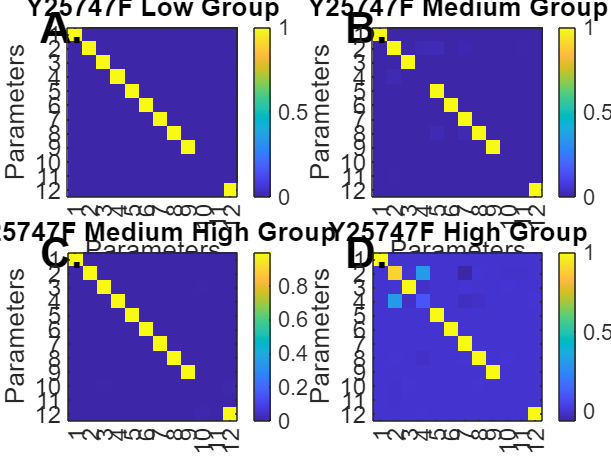

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Define the groups and corresponding files
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
groups = {'Low', 'Medium', 'Medium High', 'High'};
fitted_file_vars = {'Y25747F_low', 'Y25747F_medium', 'Y25747F_medium_high', 'Y25747F_high'};
fitted_files = load('fitted_param_Y25747F.mat', fitted_file_vars{:});

%%%%%%%%%%%%%%%%%%%%%%
% Load the dataset
%%%%%%%%%%%%%%%%%%%%%%
filename = 'Y25747_Fern_dataset.xlsx';
sheetname = 'Y25747_Fern_Grouped';
data = readtable(filename, 'Sheet', sheetname);

% Extract time data
time = downsample(data.Time, 8) / 60;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Create the figure for resolution matrices
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
fig = figure('Position', [100, 100, 1200, 900]);

% A: Low Group
h1 = subplot(2, 2, 1);
fitted_para = fitted_files.(fitted_file_vars{1});
J = calculateJacobian(@TSRP, fitted_para, time);
R = pinv(J' * J) * (J' * J);
imagesc(R);
colorbar;
title('Y25747F Low Group');
xlabel('Parameters');
ylabel('Parameters');
xticks(1:12);
yticks(1:12);
axis square;
set(gca, 'FontSize', 18);
text(-1.5, 0.5, 'A.', 'FontSize', 32, 'FontWeight', 'bold');

% B: Medium Group
h2 = subplot(2, 2, 2);
fitted_para = fitted_files.(fitted_file_vars{2});
J = calculateJacobian(@TSRP, fitted_para, time);
R = pinv(J' * J) * (J' * J);
imagesc(R);
colorbar;
title('Y25747F Medium Group');
xlabel('Parameters');
ylabel('Parameters');
xticks(1:12);
yticks(1:12);
axis square;
set(gca, 'FontSize', 18);
text(-1.5, 0.5, 'B.', 'FontSize', 32, 'FontWeight', 'bold');

% C: Medium High Group
h3 = subplot(2, 2, 3);
fitted_para = fitted_files.(fitted_file_vars{3});
J = calculateJacobian(@TSRP, fitted_para, time);
R = pinv(J' * J) * (J' * J);
imagesc(R);
colorbar;
title('Y25747F Medium High Group');
xlabel('Parameters');
ylabel('Parameters');
xticks(1:12);
yticks(1:12);
axis square;
set(gca, 'FontSize', 18);
text(-1.5, 0.5, 'C.', 'FontSize', 32, 'FontWeight', 'bold');

% D: High Group
h4 = subplot(2, 2, 4);
fitted_para = fitted_files.(fitted_file_vars{4});
J = calculateJacobian(@TSRP, fitted_para, time);
R = pinv(J' * J) * (J' * J);
imagesc(R);
colorbar;
title('Y25747F High Group');
xlabel('Parameters');
ylabel('Parameters');
xticks(1:12);
yticks(1:12);
axis square;
set(gca, 'FontSize', 18);
text(-1.5, 0.5, 'D.', 'FontSize', 32, 'FontWeight', 'bold');

% Adjust subplot positions
set(0, 'Units', 'normalized');
set(h1, 'Position', [0.06, 0.57, 0.38, 0.37]);
set(h2, 'Position', [0.56, 0.57, 0.38, 0.37]);
set(h3, 'Position', [0.06, 0.08, 0.38, 0.37]);
set(h4, 'Position', [0.56, 0.08, 0.38, 0.37]);

% Set paper size and save the figure
set(gcf, 'PaperSize', [14, 14], 'PaperPosition', [0, 0, 14, 14]);
print('Y25747F_res_matrices', '-djpeg', '-r300');

## Function to calculate the Jacobian matrix

function J = calculateJacobian(modelFunc, params, time)
    numParams = length(params);
    numTimePoints = length(time);
    perturbation = 1e-2;
    J = zeros(numTimePoints, numParams);
    
    for j = 1:numParams

        % Perturb the parameter
        paramsPerturbed = params;

        if (j ~= 12) || (params(12) == 0)
            paramsPerturbed(j) = paramsPerturbed(j) + perturbation;
        else
            paramsPerturbed(j) = paramsPerturbed(j) + perturbation*params(j);
        end
        
        % Calculate the model output with perturbed parameters
        [T_perturbed, ~, ~, ~] = modelFunc(paramsPerturbed, time);
        
        % Calculate the model output with original parameters
        [T, ~, ~, ~] = modelFunc(params, time);
        
        % Compute the Jacobian (sensitivity) for this parameter
        J(:, j) = (T_perturbed - T) / perturbation;
    end
end


## Function to normalize the resolution matrix

function R_norm = normalizeResolutionMatrix(R)
    D = diag(sqrt(diag(R)));
    R_norm = D \ R / D;
end

## Compute total host cells, susceptibles, and resistants for 1-species-1-phage model

function [T,S,R,P] = TSRP(para_fit,t)
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Pre-estimate parameters for the model
    K = 10^9; % CFU/mL
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Fitting parameters for the model
    r = para_fit(1);
    a = para_fit(2);
    a_ss = para_fit(3);
    a_rr = para_fit(4);
    delta = para_fit(5);
    gamma = para_fit(6);
    phi = para_fit(7);
    beta = para_fit(8);
    m = para_fit(9);
    S0 = para_fit(10);
    R0 = para_fit(11);
    P0 = para_fit(12);

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Compute the total host cells from the model
    initial_value = [S0;R0;P0];
    p = [r,a,a_ss,a_rr,K,delta,gamma,phi,beta,m];
    func = @one_species_one_phage;
    [~,y] = ode15s(@(r,y) func(r,y,p),t,initial_value);
    T = y(:,1) + y(:,2);
    S = y(:,1);
    R = y(:,2);
    P = y(:,3);
end

## Vector field for 1-species-1-phage model

function dy = one_species_one_phage(t,y,p)
    %%%%%%%%%%%%%%%
    r = p(1); % growth rate of S in the absence of P and R
    a = p(2); % interspecific competition coefficient of S and R
    a_ss = p(3); % intraspecific competition coefficient of S
    a_rr = p(4); % intraspecific competition coefficient of R
    K = p(5); % system-wide carrying capacity
    delta = p(6); % rate of resistance acquisition
    gamma = p(7); % fitness cost of phage resistance (rel. to parental phenotype)
    phi = p(8); % the adsorption rate of P when attaching to S
    beta = p(9); % burst size of phage P when infecting S
    m = p(10); % decay rate of phage P
    %%%%%%%%%%%%%%%
    dy = zeros(3,1);
    dy(1) = r*y(1)*(1-(a_ss*y(1) + a*y(2))/K) - delta*y(1) - phi*y(3)*y(1);
    dy(2) = gamma*r*y(2)*(1-(a*y(1) + a_rr*y(2))/K) + delta*y(1);
    dy(3) = beta*phi*y(3)*y(1) - m*y(3);
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %  y(1) represents the population density of phage-susceptible bacteria S
    %  y(2) represents the population density of phage-resistant bacteria R
    %  y(3) represents the population density of phage P
    %  p = [r,a,a_ss,a_rr,K,delta,gamma,phi,beta,m]
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%
end
